# **BSP 2021-2022/1 - Assignment 04**

  **Total of 10 marks**

**Name/Neptun Code: **                                    

**Marks attained for this homework will count towards your final grade**

**To attain (full) marks for a question, any answer that includes images or a piece of knowledge, which should be referenced/cited, needs to highlight the source (book, article or web address). You are encouraged to help each other, but identical solutions will not be graded.**

## **The P300, "oddball" paradigm**

*Watch the video: *[link to video](https://www.youtube.com/watch?v=9SIBtW1QqT8)

*Protocol*: in a sequence standard and deviant tones are played for the participant. The deviant sound is different in frequency and amplitude. The listener has to push a button when a deviant sound is detected.

The P300 evoked potential is a positive response (mind the axes below) on the EEG signal at 300 ms, corresponding to the anticipation of the deviant tone.  

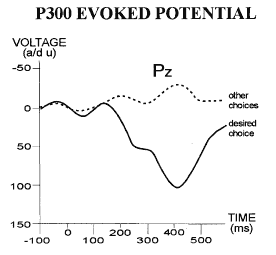

However, we do know that EEG signals are extreamly noisy, as we are working with very low-apmplitude signals. For this reason, a single measurement cannot detect this change. In the protocol the EEG response is recorded multiple times, and a synchronized averaging is performed on the 'standard' and 'deviant' measurements.

### The signal

The data contains 3 columns:

- BNC - the sound tones

- EEG

- the button pushes

The measurement started at 178 s after the recording was turned on. Cut the first 178 s from all 3 columns, and plot the spectrum of the EEG signal, if the sampling frequency was 2 kHz.

clear all
load BSP_P300.mat
fs = 2000; % Hz
% cropping of the data
important_start = 178*1000;
data = data(important_start:end,:);
Ns = size(data,1); % number of samples


BNC = data(:,1);
EEG = data(:,2);
Button = data(:,3);

% time array
t = linspace(0,(Ns-1)/fs,Ns) ;
% frequency array
f = linspace(0,fs/2,Ns/2) ;
% Spectrum of the EEG signal
fEEG = fft(EEG);
fEEG = abs(fEEG(1:Ns/2));
figure
plot(f,fEEG )
xlabel('frequency (Hz)')
ylabel('spectrum')

(1 mark)

#### Question 1

Inspect the plotted spectrum. Explain, what can be seen at 50 Hz, 100 Hz, 150 Hz, etc.

 At 50 Hz it's clear that data nearly ends noise emerges after 50 Hz. As we can see at 100Hz, 150 Hz there are noises. We are going to filter that part on next one.                                                                                                                            

(1 mark)

### Prefiltering of the signal

Here you can see the characteristic spectrum of an EEG signal.

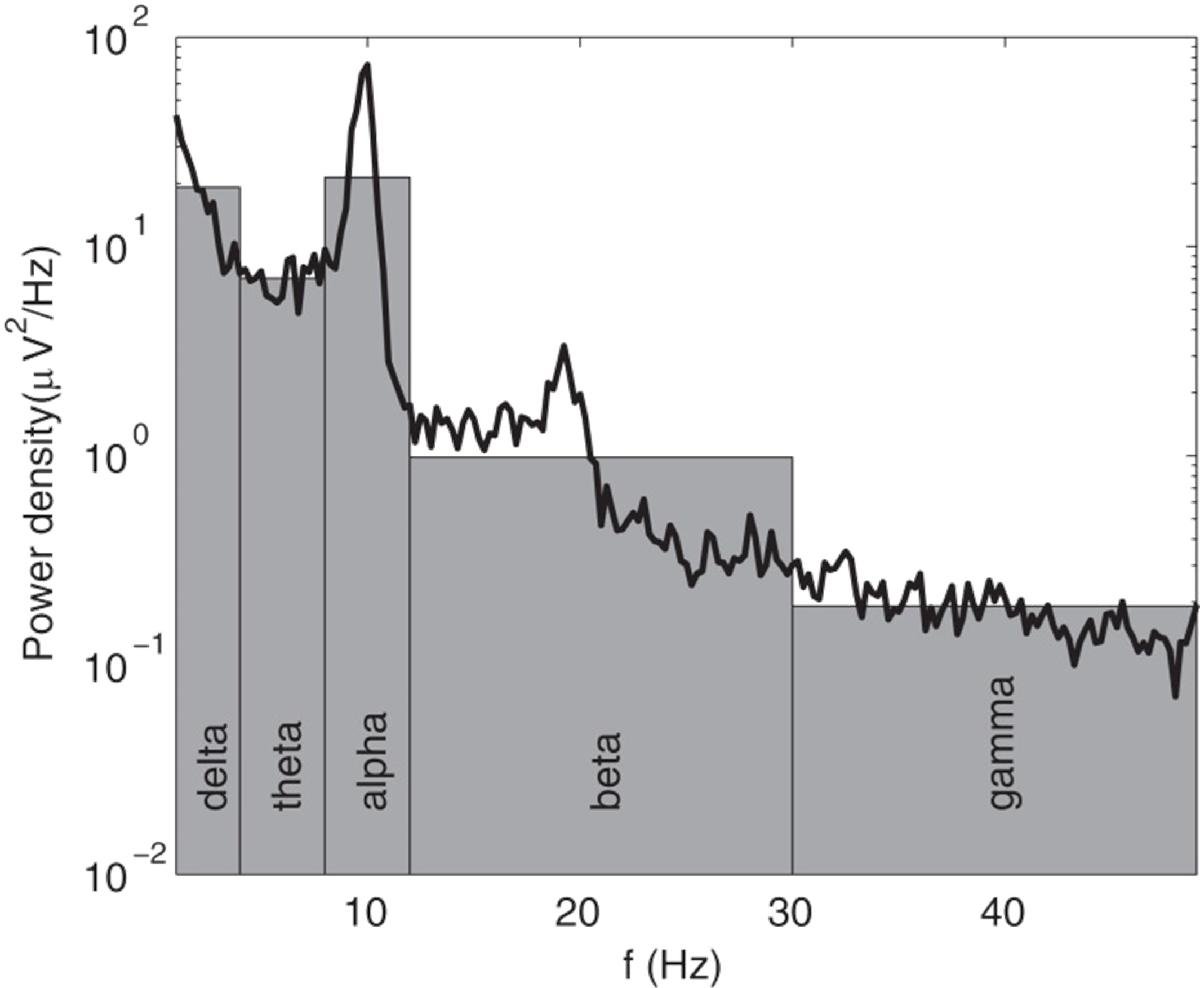

It is visible that all important EEG information is stored in the <50Hz range. Design a butterworth LPF for eliminating any higher frequency noise.

fc = 50;
[b,a] =  butter(9,fc/(fs/2),'low');
% Inspect the Bode diagram of the filter
figure
freqz(b,a,fs,fs);

% use filtfilt to avoid signal delay
EEG_prefilt = filtfilt(b,a,EEG);
fEEG_prefilt = fft(EEG_prefilt);
fEEG_prefilt = abs(fEEG_prefilt(1:Ns/2));


figure
alpha = mean(fEEG_prefilt(8:14));
beta = mean(fEEG_prefilt(14:30)); 
teta = mean(fEEG_prefilt(4:8));
delta = mean(fEEG_prefilt(1:4));
gama = mean(fEEG_prefilt(30:50));

plot(f(1:4),delta,f(4:8),teta,f(8:14),alpha,f(14:30),beta,f(30:50),gama)
hold on
plot(f,fEEG_prefilt(1:round(Ns/2)))
xlabel('frequency (Hz)')
ylabel('spectrum')


(1 mark)

#### Question 2

What is the phase response of the filter defined by 'b' and 'a'? 

ba_respone = "non-linear phase"

What is the phase response of the filtering, using the filtfilt() function?

filtfilt_response = "zero-phase"

If a 100 Hz component has a magnitude of 0.1 uV, what will be its amplitde after filtering?

dampened_magnitude = 0.1*filter(b,a,fEEG_prefilt(100));

(2 marks)

### Separating the deviant and standard tones

The deviant tones have an amplitude above 0.5 V, while standard tones are peaking between 0.37 - 0.39 V. 

figure
plot(t,BNC)
xlabel('ttime (s)')
ylabel('V')

%finding all the peaks
[pks, locs] = findpeaks(BNC,'MinPeakHeight',0.2,"MinPeakDistance",0.5*fs);
hold on
plot(t(locs),pks,'k*')

% picking only the higher amplitude, deviant peaks
dev_locs = locs(pks> 0.5);
dev_pks = pks(pks>0.5);
plot(t(dev_locs),dev_pks,'r*')

% picking only the lower amplitude, standard peaks
std_locs = locs(pks< 0.39);
std_pks = pks(pks<0.39);
plot(t(std_locs),std_pks,'g*')


(1 mark)

### Averaging the deviant and standard EEG snippets

The tones located above signal the onset, '0 s' for the P300 signal. These will help us to do the synchronized averaging, this is the 'synchronous event'.

Use the std_locs and dev_locs arrays for finding the corresponding EEG_prefilt snippets. Cut 800 ms sections of the EEG_prefilt signal.

Without averaging, the segments look like this:

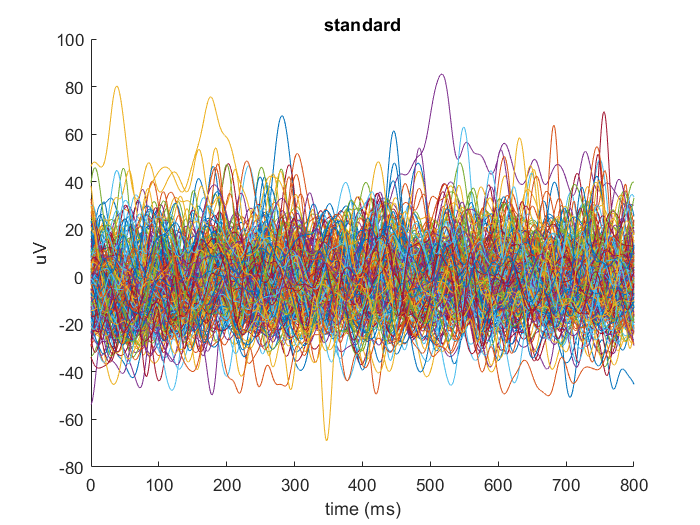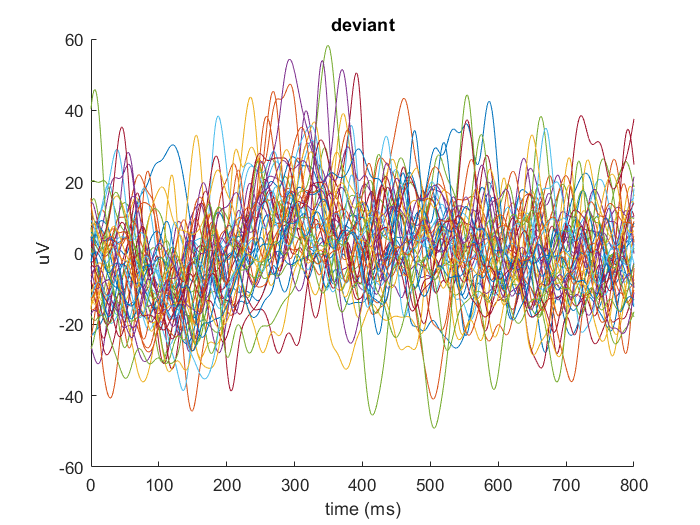

 For showing the P300 shift properly, these segments will have to be averaged.

% number of samples in 800 ms-long recording
Np300 = .;

% averaging the standard EEG responses
EEG_std = zeros(Np300,1);
% this might actually be multiple lines...
 

% averaging the deviant EEG responses
EEG_dev = zeros(Np300,1);
% this might actually be multiple lines...
 

t_short = linspace(0,Np300/fs,Np300);

figure
plot(t_short*1000,EEG_std)
hold on
plot(t_short*1000,EEG_dev)
legend('normal','deviant')
xlabel('time (ms)')
ylabel('uV')
title('filtered')

(2 marks)

Ideally you should see on the output something similar:

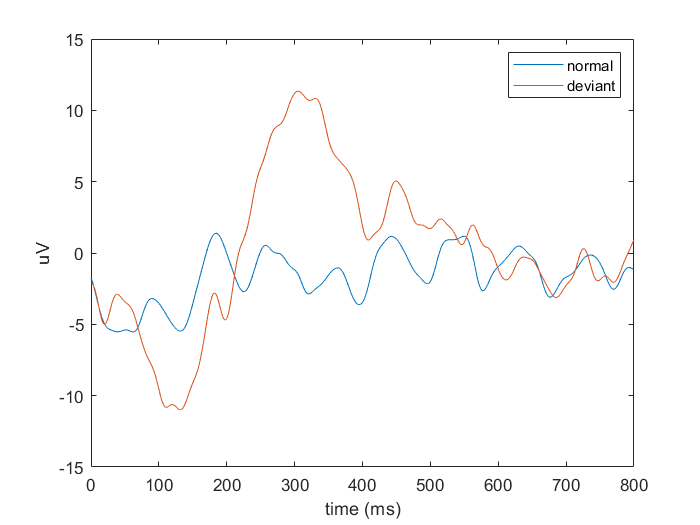

Repeat the previous section with the unfiltered EEG signal. Plot the result.

% averaging the standard EEG responses
EEG_std_unf = zeros(Np300,1);
% this might actually be multiple lines...
 

% averaging the deviant EEG responses
EEG_dev_unf = zeros(Np300,1);
% this might actually be multiple lines...
 

t_short = linspace(0,Np300/fs,Np300);

figure
plot(t_short*1000,EEG_std_unf)
hold on
plot(t_short*1000,EEG_dev_unf)
legend('normal','deviant')
xlabel('time (ms)')
ylabel('uV')
title('unfiltered')

Invalid use of operator.

#### Question 3

Remember the conditions of synchronized averaging. What noise component is causing the difference between the two previous plots? Give an explanation.

  It is because of 50Hz city line electricity. When we measure while we are connected to power line it's expected to see noise.                                                                                                                          

Where is the noise dampening stronger? In the averaged deviant, or standard signal? Why?

(2 marks)

**Do not forget to generate a pdf report from this file (Save/ Export to PDF). You should upload both the pdf and mlx files to moodle.**